img1 = imread("1_SnowPoolsBefore_20180113_md-2048px.jpg");
img2 = imread("2_SnowPoolsAfter_20200119_md-2048px.jpg");

Let's visualize the images

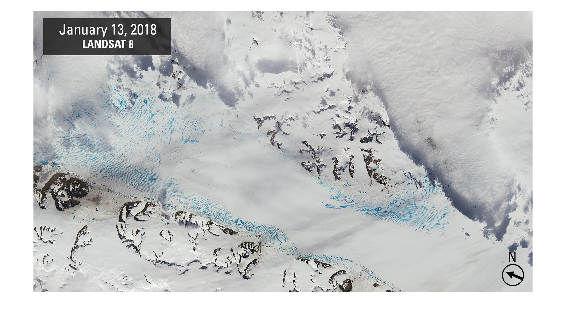

imshow(img1)

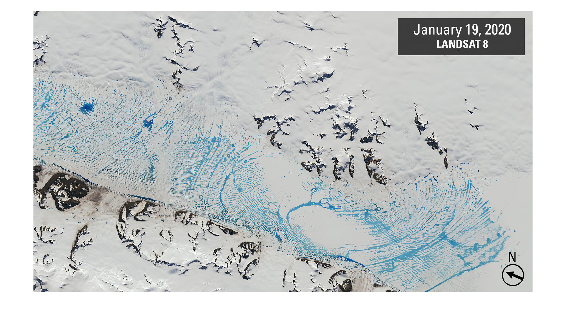

imshow(img2)

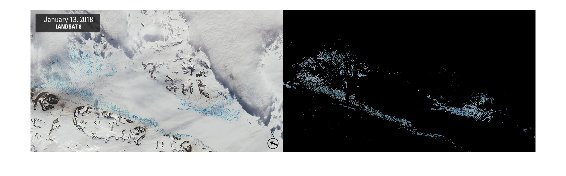

% Run this to make sure your function works properly before pressing Submit
img1 = imread("1_SnowPoolsBefore_20180113_md-2048px.jpg");
img2 = imread("2_SnowPoolsAfter_20200119_md-2048px.jpg");
[BW1, maskedImg1] = segmentMeltwater(img1);
[BW2, maskedImg2] = segmentMeltwater(img2);
figure
montage({img1, maskedImg1})

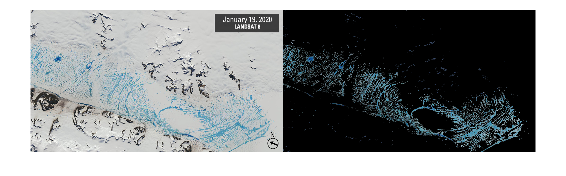

figure
montage({img2, maskedImg2})

Let's get the overall increase

(nnz(BW2) - nnz(BW1)) / nnz(BW1) * 100

ans = 157.1441

Let's save images

imwrite(maskedImg1,"2018Water.jpg","Quality",100)
imwrite(maskedImg2,"2020Water.jpg","Quality",100)